# Lab - 04

format long e

## **Question - 1**

(4/3 - 1)*3 - 1

ans =     -2.220446049250313e-16


5*((1+exp(-50)) - 1)/((1 + exp(-50)) - 1)

ans =    NaN


log(exp(750))/100

ans =    Inf


We observe that the result of the mentioned expressions is same as it is mentioned in the question, the reason to which is catastrophic cancellation, i.e. the blowing up of error due to round-off while evaluating some operator over floating point numbers. 

For example in 1st expression, 4/3 = 1.3333... which on further evaluating, leaves the rounding error -2.2204e-16 instead of a perfect 0. 

In 2nd expression, due to roundoff error, exp(-50) is treated as 0, which makes the expression a 0/0 form giving NaN.

In 3rd expression, again due to roundoff errors, exp(750) blows up to Inf, making it's log to be Inf as well.

## **Question - 2**

p = (1:16)'; x_array = 10.^(-p);

f1 = @(x) (tan(x) - x)./x.^(3);
f2 = @(x) (exp(x) + cos(x) - sin(x) - 2) ./ x.^3;
f3 = @(x) (exp(x) - 1) ./ x;

f1_hat = @(x) 1/3 + 2*x.^2/15 + 17*x.^4/315;
f2_hat = @(x) 1/3 + x/12 + x.^4/2520 + x.^5/20160;
f3_hat = @(x) 1 + x/2 + x.^2/6 + x.^3/24 + x.^4/120;

2 (i)

vals_actual = f1(x_array);
vals_approx = f1_hat(x_array);

E_actual = abs(1/3 - vals_actual);
E_approx = abs(1/3 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -2.873299829331332e+00
     2.000000000000000e+00    -4.875043663184115e+00
     3.000000000000000e+00    -6.874849849102898e+00
     4.000000000000000e+00    -8.496812199889503e+00
     5.000000000000000e+00    -6.339513653567319e+00
     6.000000000000000e+00    -4.587227263120465e+00
     7.000000000000000e+00    -2.608872802071586e+00
     8.000000000000000e+00    -4.771212547196625e-01
     9.000000000000000e+00    -4.771212547196625e-01
     1.000000000000000e+01    -4.771212547196625e-01


[p log10(E_approx)]

ans =      1.000000000000000e+00    -2.873306952774722e+00
     2.000000000000000e+00    -4.875043685162658e+00
     3.000000000000000e+00    -6.875061087690836e+00
     4.000000000000000e+00    -8.875061263620294e+00
     5.000000000000000e+00    -1.087506122745802e+01
     6.000000000000000e+00    -1.287504676278810e+01
     7.000000000000000e+00    -1.487540852414338e+01
     8.000000000000000e+00                      -Inf
     9.000000000000000e+00                      -Inf
     1.000000000000000e+01                      -Inf


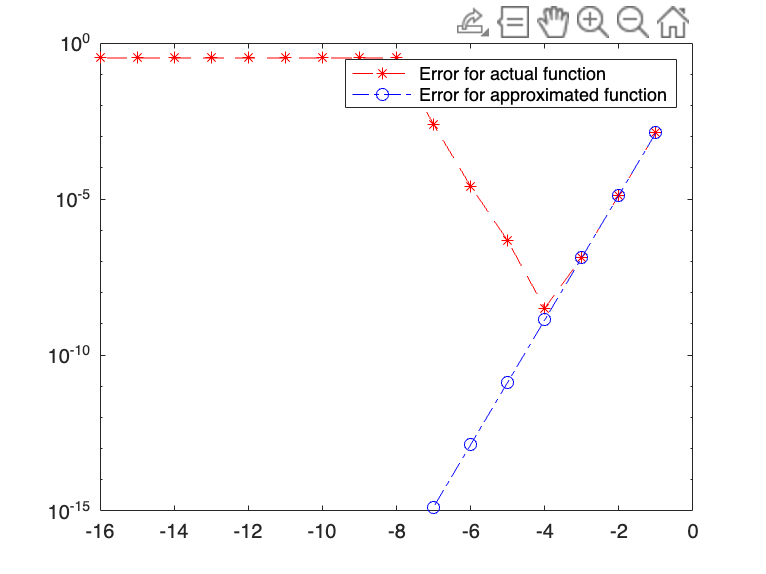


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;

Smallest p for which expression gives no correct significant digits = 8, as the error reaches 10^0.

2 (ii)

vals_actual = f2(x_array);
vals_approx = f2_hat(x_array);

E_actual = abs(1/3 - vals_actual);
E_approx = abs(1/3 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -2.079179152122654e+00
     2.000000000000000e+00    -3.079181185832042e+00
     3.000000000000000e+00    -4.078228486147827e+00
     4.000000000000000e+00    -3.750402363212019e+00
     5.000000000000000e+00    -9.556332215736859e-01
     6.000000000000000e+00    -4.771212547196625e-01
     7.000000000000000e+00     5.346440877435310e+00
     8.000000000000000e+00    -4.771212547196625e-01
     9.000000000000000e+00    -4.771212547196625e-01
     1.000000000000000e+01    -4.771212547196625e-01


[p log10(E_approx)]

ans =      1.000000000000000e+00    -2.079179152132846e+00
     2.000000000000000e+00    -3.079181243976963e+00
     3.000000000000000e+00    -4.079181246045648e+00
     4.000000000000000e+00    -5.079181246047673e+00
     5.000000000000000e+00    -6.079181246044779e+00
     6.000000000000000e+00    -7.079181245986920e+00
     7.000000000000000e+00    -8.079181244829726e+00
     8.000000000000000e+00    -9.079181239043763e+00
     9.000000000000000e+00    -1.007918121011394e+01
     1.000000000000000e+01    -1.107918121011394e+01


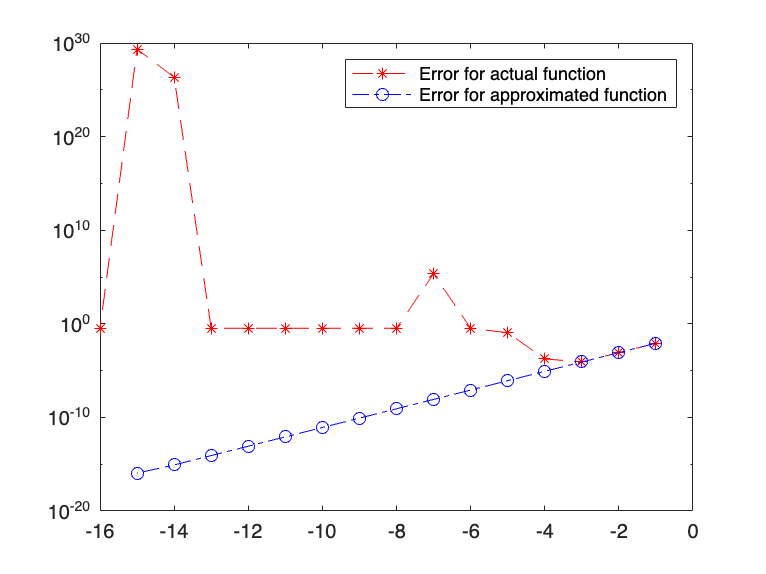


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;

Smallest p for which expression gives no correct significant digits = 5, as the error reaches 10^0.

2 (iii)

vals_actual = f3(x_array);
vals_approx = f3_hat(x_array);

E_actual = abs(1 - vals_actual);
E_approx = abs(1 - vals_approx);

[p log10(E_actual)]

ans =      1.000000000000000e+00    -1.286432342826650e+00
     2.000000000000000e+00    -2.299581140482518e+00
     3.000000000000000e+00    -3.300885218735133e+00
     4.000000000000000e+00    -4.301015515302865e+00
     5.000000000000000e+00    -5.301029390700364e+00
     6.000000000000000e+00    -6.301062843767653e+00
     7.000000000000000e+00    -7.305977055789310e+00
     8.000000000000000e+00    -8.216277106889963e+00
     9.000000000000000e+00    -7.082282536105524e+00
     1.000000000000000e+01    -7.082282536105524e+00


[p log10(E_approx)]

ans =      1.000000000000000e+00    -1.286432461164006e+00
     2.000000000000000e+00    -2.299581140493628e+00
     3.000000000000000e+00    -3.300885218772343e+00
     4.000000000000000e+00    -4.301015519059760e+00
     5.000000000000000e+00    -5.301028548015156e+00
     6.000000000000000e+00    -6.301029850761315e+00
     7.000000000000000e+00    -7.301029980945499e+00
     8.000000000000000e+00    -8.301029998303393e+00
     9.000000000000000e+00    -9.301029959730297e+00
     1.000000000000000e+01    -1.030102995973030e+01


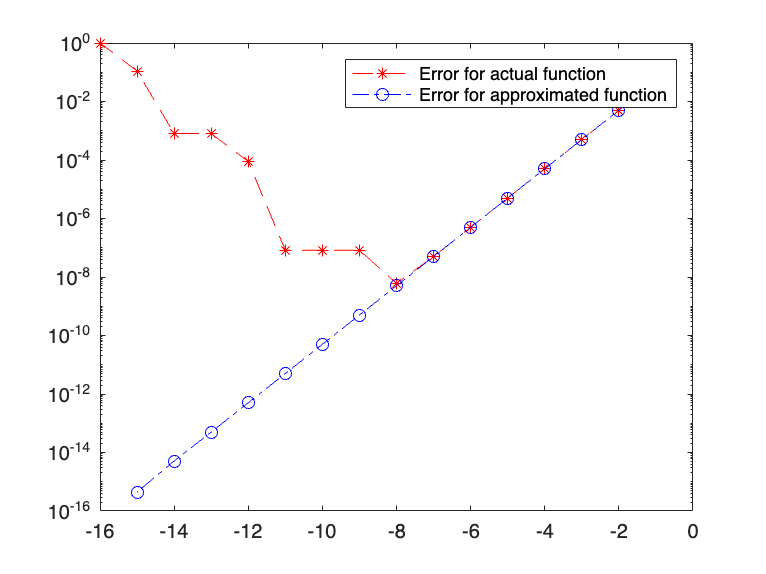


semilogy(-p, E_actual, 'r*--');
hold on;
semilogy(-p, E_approx, 'bo-.');
legend('Error for actual function', 'Error for approximated function');
hold off;

Smallest p for which expression gives no correct significant digits = 16, as the error reaches 10^0.

### **Explanation**

Due to catastrophic cancellation in the subtraction operation the error due to loss of significant digits makes the output absurd and far from the original value, however when we approximate the given expressions by their taylor expansions and ignore the higher order terms, we get a polynomial expression with only addition and multiplication operations for which the rounding error is bounded, hence the value of expression around 0 is given better by the taylor approximations of those expressions.

Q3 (a)

p = [1 -8 16];
x = 0;

disp("****** Evaluation at Scalar value *******");

****** Evaluation at Scalar value *******


fprintf("x = ");

x = 

disp(x);

     0



fprintf("Calculated using Horner formula = ");

Calculated using Horner formula = 

disp(Horner(p, x));

    16




fprintf("Calculated using exact formula = ");

Calculated using exact formula = 

disp(f(x));

Unrecognized function or variable 'f'.


x = [1, 2, 4];
fprintf("\n\n****** Evaluation at Vector value *******\n");
fprintf("x = ");
disp(x);
fprintf("Calculated using Horner formula = ");
hor = Horner(p, x);
disp(hor);

fprintf("Calculated using exact formula = ");
disp(exact(x));

fprintf('Norm of error:')
disp(norm(hor - exact(x)));

**Explanation:**

We get the norm of the error as 0, which means that the calculated value of the polynomial at the given point differs from the actual value by a less that the machine epsilon(order of 10^-16).

3 (b)

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];

a = [1.95, 1.96, 1.97, 1.98, 1.99, 1.96];
b = [2.05, 2.04, 2.03, 2.02, 2.01, 1.99];

for i = 1 : length(a)
    x = bisect(p, a(i), b(i), 1e-8);
    fprintf("Computed Root for root in [%f, %f] = ", a(i), b(i));
    disp(x);
end

**Observation and Explanation:**

When we calculate the root of the polynomial, we notice that the result isn't exactly 2; there is a slight difference. 

However, as we make the interval smaller, the absolute difference between the computed root and the actual root of 2 also decreases. This variation is due to the limitations of finite precision in arithmetic and the rounding errors that occur when using Horner's method to evaluate the polynomial. As a result the computed roots are in the neighbourhood of 2.

Additionally, even in the final interval where 2 isn't included, we still find a solution that is near 2.

3 (c)

x_min = 1.93;
x_max = 2.08;
x = linspace(x_min, x_max, 151);

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
y_horner = Horner(p, x);

y_direct = (x - 2) .^ 9;

figure;
plot(x, y_horner, "blue");
hold on;
plot(x, y_direct, "red");
hold off;

xlabel("x");
ylabel("p(x)");
title("Computation of polynomials using different methods");
legend(["Horner method", "Direct formula"]);

**Explanation:**

1) We can see that the plots for the Horner method and the direct formula don’t exactly match; they differ from each other. The plot for the Horner method crosses the x-axis multiple times and shows a lot of small variations along the line.

2) This behavior could be due to rounding errors that occur when evaluating the polynomial p(x) using Horner’s method, as well as the limitations of finite precision in computing systems.

3) These small rounding errors cause the values of p(x) to fluctuate, especially around x=2. As a result, small positive values can be pushed to negative values near 2. This causes the graph to cross the x-axis at multiple points, not just at 2. Theoretically, the root should only be 2, with a multiplicity of 9, but computationally, there are roots in the vicinity of 2, even in intervals that don’t actually contain 2 (Seen in the interval [1.96, 1.99], in previous subpart).

4) There’s also the possibility of catastrophic cancellation occurring in Horner’s method due to the multiplication and addition at each step in the computation process.

**Functions**

function y = exact(x)
    y = (x - 4) .^ 2;
end

function y = Horner(p, x)
    n = length(p) - 1;
    y = p(1);

    for i = 2:n+1
        y = y.*x + p(i);
    end
end

function x = bisect(p, x0, x1, tol)
    x = (x0 + x1) / 2;
    while x1 - x0 > 2*tol
        [a, b, c] = deal(Horner(p, x0), Horner(p, x), Horner(p, x1));
                
        if a * b < 0
            x1 = x;
        else
            x0 = x;
        end
        
        x = (x0 + x1) / 2;
    end
end